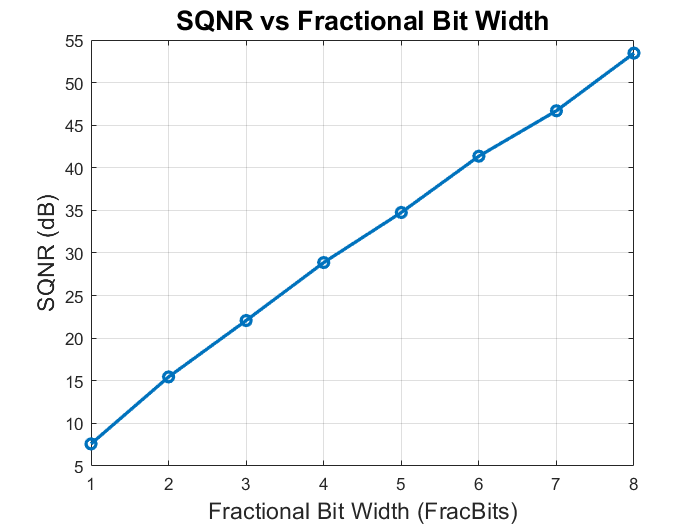

clc; clear;

NumOfInputSamples_N = 8;
nSeeds = 100;

fracBitsRange = 1:1:8;   % fractional bit widths to test
SQNR_dB = zeros(size(fracBitsRange));

for fIdx = 1:length(fracBitsRange)
    fracBits = fracBitsRange(fIdx);
    
    % Define fixed-point numerictype: signed, wordlength=32, fractional length varies
    T = FFT_8_Point_Radix_2_types('FxPt',fracBits);
    
    signalPower = 0;
    noisePower  = 0;
    
    for seed = 1:nSeeds
        rng(seed);
        % Create random input
        FFT_Golden_In = rand(1, NumOfInputSamples_N);
        FFT_Algo_In   = cast(FFT_Golden_In, 'like', T.FFT_Algo_In);
        
        % Fixed-point FFT
        FFT_Algo_Out  = FFT_8_Point_Radix_2(FFT_Algo_In, T);
        
        % Reference (double precision)
        FFT_Golden_Out = fft(FFT_Golden_In);
        
        % Accumulate signal and noise power
        signalPower = signalPower + sum(abs(FFT_Golden_Out).^2);
        noisePower  = noisePower  + sum(abs(double(FFT_Algo_Out) - FFT_Golden_Out).^2);
    end
    
    SQNR_dB(fIdx) = 10*log10(signalPower / noisePower);
end

% Plot
figure;
plot(fracBitsRange, SQNR_dB, 'o-', 'LineWidth',2);
grid on;
xlabel('Fractional Bit Width (FracBits)','FontSize',14);
ylabel('SQNR (dB)','FontSize',14);
title('SQNR vs Fractional Bit Width','FontSize',16);